% This live script is used to test the upsampling function
% for the ECE 434 DSP CPX3 project
%
% Author: Ben Cometto
% 20 Nov 24

% This worked wonderfully before the lpf
% data = [ 1 2 2 1; 
%     3 4 3 2; 
%     5 5 4 5; 
%     6 6 6 6; 
%     6 8 6 9; 
%     7 8 7 9; 
%     9 9 8 11; 
%     11 10 9 13;
%     11 12 11 13;
%     13 14 12 16;
%     13 15 14 17;
%     14 14 15 18;
%     15 13 13 20;]

Fs = 100000;
n = 1:200;
t = n*T;
T = 1/Fs;
k = n

k =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


df = Fs/length(k); % Fs/N
f = k*df;

data = [sin(30000*n*T); sin(45000*n*T); 5*n.^0; cos(20000*n*T) + 2*cos(10000*n*T) + 3*sin(25000*n*T)]'

data =    0.295520206661340   0.434965534111230   5.000000000000000   3.712286786160861
   0.564642473395035   0.783326909627483   5.000000000000000   4.319470765497977
   0.783326909627483   0.975723357826659   5.000000000000000   4.780924873230893
   0.932039085967226   0.973847630878195   5.000000000000000   5.063241651776625
   0.997494986604054   0.778073196887921   5.000000000000000   5.142421287715644
   0.973847630878195   0.427379880233830   5.000000000000000   5.005513944108193
   0.863209366648874  -0.008407247367149   5.000000000000000   4.651609358091028
   0.675463180551151  -0.442520443294852   5.000000000000000   4.092106176870087
   0.427379880233830  -0.788525254426196   5.000000000000000   3.350237432512006
   0.141120008059867  -0.977530117665097   5.000000000000000   2.459874207501007



load lpf_upsample.bin -mat
tic
data_u = upsampling(data,num_upsample)

data_u =    0.000958291578328   0.001410474812910   0.016213638809244   0.012037935421428
  -0.001828057025515  -0.002690651206130  -0.030929475959830  -0.022963816981711
  -0.013538558500272  -0.020081756177224  -0.243828483147616  -0.179063318869362
  -0.024033365311318  -0.035078467237790  -0.378461483703423  -0.284747489463030
  -0.017796308165591  -0.024285042569710  -0.091051429326261  -0.095715183278484
  -0.015238851657050  -0.018014277360779   0.109711445656939   0.032642413314059
  -0.043762850970642  -0.057945235086223  -0.485245867153431  -0.392919012541825
  -0.062366804995055  -0.081677164636992  -0.859489761814368  -0.661486393951988
   0.010000835896843   0.031530036000940   0.797594067697138   0.511339052743589
   0.171196276153746   0.275861541071250   3.795352569422437   2.701780112849053


toc

Elapsed time is 0.004321 seconds.



FsU = 2*Fs;
nU = 1:length(data_u(:,1));
tU = nU/FsU;
kU = nU;
dfU = FsU/length(kU)

dfU =    500


fU = kU*dfU;


% ===== Analysis: Does it work =====
% Notes: fc at fs/2
%        Scaled by 1/L so multiply by L
%        Can probably speed up with lower order, and can test several other
%        methods of doing the zero padding

col = 3

col =      3


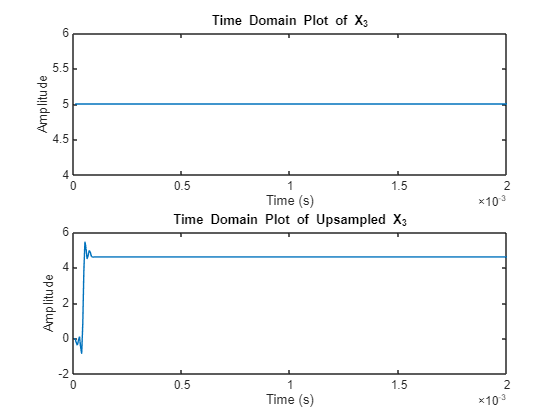


Data = abs(fft(data));
Data_U = abs(fft(data_u));

figure
subplot(2,1,1)
plot(t,data(:,col))
title(sprintf("Time Domain Plot of X_%i",col))
xlabel("Time (s)")
ylabel("Amplitude")

subplot(2,1,2)
plot(tU,data_u(:,col))
title(sprintf("Time Domain Plot of Upsampled X_%i",col))
xlabel("Time (s)")
ylabel("Amplitude")

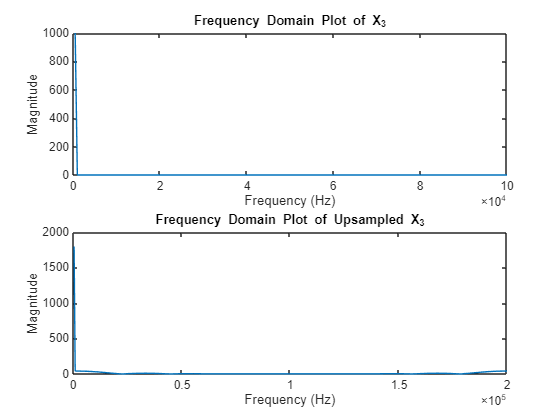



figure
subplot(2,1,1)
plot(f,Data(:,col))
title(sprintf("Frequency Domain Plot of X_%i",col))
xlabel("Frequency (Hz)")
ylabel("Magnitude")
subplot(2,1,2)
plot(fU,Data_U(:,col))
title(sprintf("Frequency Domain Plot of Upsampled X_%i",col))
xlabel("Frequency (Hz)")
ylabel("Magnitude")





% ===== Analysis: Speed =====
% notes: lots of variation... finally at 100k iterations its pretty stable
% at 1.8e-5 s

iterations = 100000

iterations =       100000


sum = 0;

for k=1:iterations
    time1 = tic;
    upsampling(data,num_upsample);
    time2 = toc(time1);

    sum = sum + time2;
end

averageRuntime = sum/iterations

averageRuntime =      1.749649799999749e-05
